# Testing the Function SNHT_floor

## Simple Test Plane

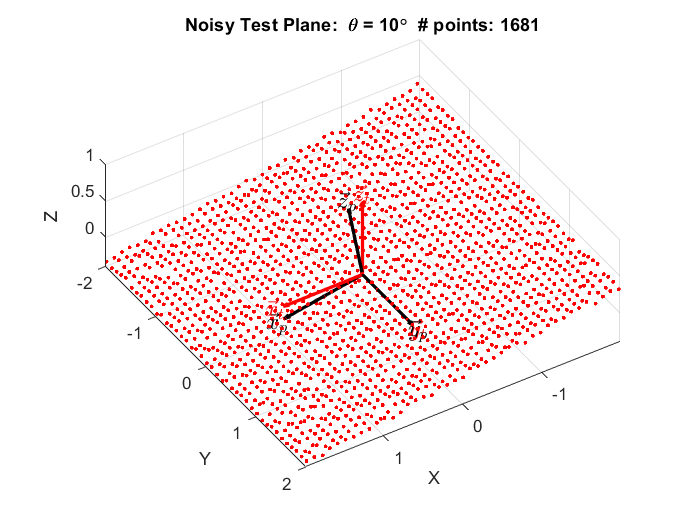

addpath("Nav_Functions")

% Build a Somewhat Noisy Test Plane
phi   = 0;
theta = 10 * pi/180;
C = rotate_y(theta) * rotate_x(phi);
org = [0, 0, 0];
dim = 2 * [-1 1; -1 1];
dx = 0.1; dy = 0.1;
sigmas = [0; 0; 0.025];
color = 'r';

% Generate Point Cloud using the Same Parameters
xyz = gen_plane(C, org, dim, dx, dy, sigmas);

figure
plot_plane(C, org, dim, dx, dy, sigmas, color);
plot_frame(eye(3), zeros(3,1), 't', 'r');
plot_frame(C, org, 'p', 'k');
title_str = ['\theta = ', num2str(theta * 180/pi), '\circ']; 
title(['Noisy Test Plane:  ', title_str, '  # points: ', num2str(length(xyz))])
xlabel('X')
ylabel('Y')
zlabel('Z')
% xlim([-1 3])
% ylim([-1 1])
% zlim([-1.5 1.5])
view([147.66 39.39])
axis equal
grid on

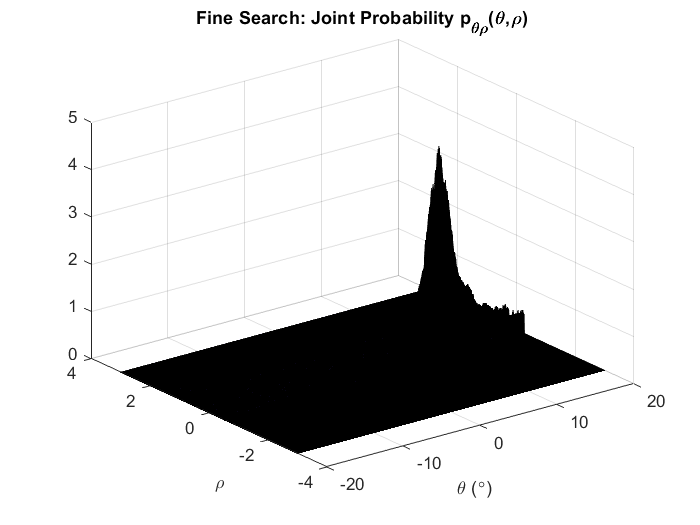

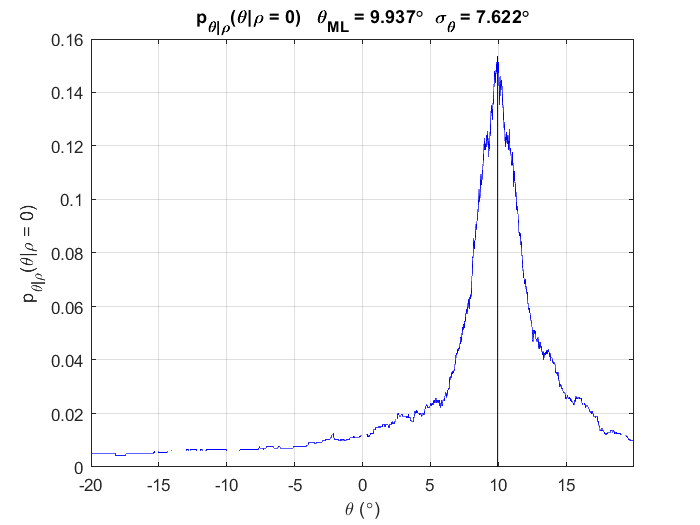

% Test the Algorithm
plot_flag = true;
tic
[theta_ML, theta_var] = SNHT_Pitch_Only(xyz, plot_flag);

toc

Elapsed time is 28.178560 seconds.
